# This code is for filtering the data with random trigger and plotting the ion specific electron KE spectra

clear
%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\Ada_PEPICO_hv350eV_ke260_0003_ana';
raw_data = IO.import_raw(dir);
addpath('E:\PhD\Adamantane_data\mdata')
mdata = md_all();                                                                                                          
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


## Event statistics from all data

e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); % electron trigger
RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); % rnd trigger

[e_filter_et, ~]	= macro.filter.conditions_2_filter(data_converted,e_TRG);
data_stats.N_e = sum(e_filter_et);
[e_filter_rt, ~]	= macro.filter.conditions_2_filter(data_converted, RND_TRG);
data_stats.N_RND = sum(e_filter_rt);

%probability to detect j ions after electron trigger
for j =0:4
    etN =struct();
    etN.e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); %electron trigger
    etN.ions= macro.filter.write_coincidence_condition(j, 'det2');
    [e_filter_etN, ~]	= macro.filter.conditions_2_filter(data_converted,etN);
    strg = ['etP_',num2str(j)];
    data_stats.(strg) = sum(e_filter_etN)/data_stats.N_e;
end

%probability to detect j ions after RND trigger
for j =0:4
    rtN =struct();
    rtN.RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); %RND trigger
    rtN.ions= macro.filter.write_coincidence_condition(j, 'det2');
    [e_filter_rtN, ~]	= macro.filter.conditions_2_filter(data_converted,rtN);
    strg = ['rtP_',num2str(j)];
    data_stats.(strg) = sum(e_filter_rtN)/data_stats.N_RND;
    
end

## step 1 filtering for electron KE and ion TOF range

ion_cond.hit1.type		= 'discrete'; %'continuous'; %
ion_cond.hit1.data_pointer	= 'h.det2.m2q_l';
ion_cond.hit1.value		= 12*3+5;%mdata.sample.fragment.masses; %[44; 1e4]
ion_cond.hit1.translate_condition	= 'OR';
ion_cond.hit1.invert_filter         = false;

[e_filter_ion, ~]	= macro.filter.conditions_2_filter(data_converted,ion_cond);
hit_filter_ion = filter.events_2_hits_det(e_filter_ion, data_converted.e.raw(:,1), length(data_converted.h.det1.KER),...
    ion_cond, data_converted); 
filter to keep only electrons detected in coincidence with the specific ion
ES_ion_no_filt = data_converted.h.det1.KER;%(hit_filter_ion); %%pa

## Make Electron spectrum

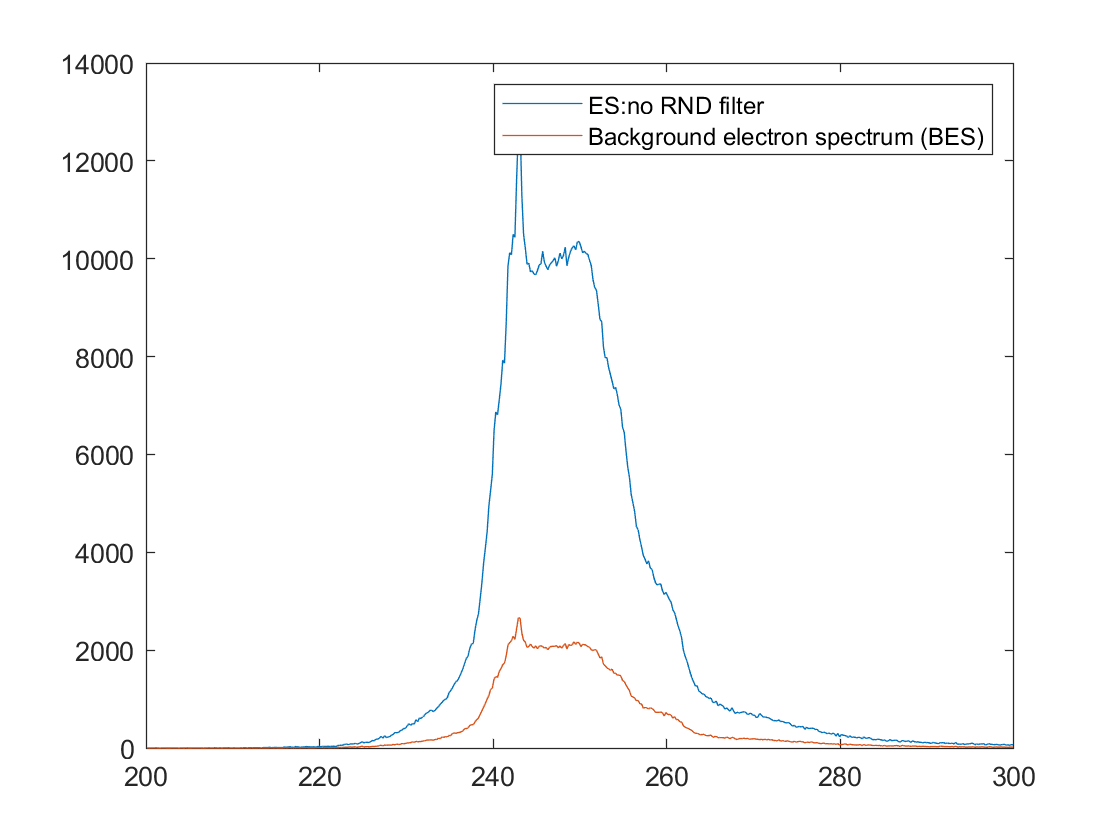

binsize = 0.2;
figure
edges = 200:binsize:300;
centres = edges(1:end-1)+ diff(edges)/2;
[ES_1,edges] = histcounts(ES_ion_no_filt,edges);
plot(centres,ES_1,'DisplayName','ES:no RND filter')
legend
hold on

%define constants for RND backgrounds BES

c1 = data_stats.rtP_1/data_stats.rtP_0;

% define ES_0 Electron spectra with zero ions
zero_ion_cond= macro.filter.write_coincidence_condition(0, 'det2');
[e_filter_ion1, ~]	= macro.filter.conditions_2_filter(data_converted,zero_ion_cond);
hit_filter_ion = filter.events_2_hits_det(e_filter_ion1, data_converted.e.raw(:,1), length(data_converted.h.det1.KER),...
    zero_ion_cond, data_converted); 

% filter to keep only electrons detected in coincidence with the specific ion
ES_zero_ion = data_converted.h.det1.KER(hit_filter_ion); %%pa
[ES_0,edges] = histcounts(ES_zero_ion,edges);

%calculate the RND backgrounds BES
BES_1= c1 * ES_0;
plot(centres,BES_1, 'DisplayName','Background electron spectrum (BES)')

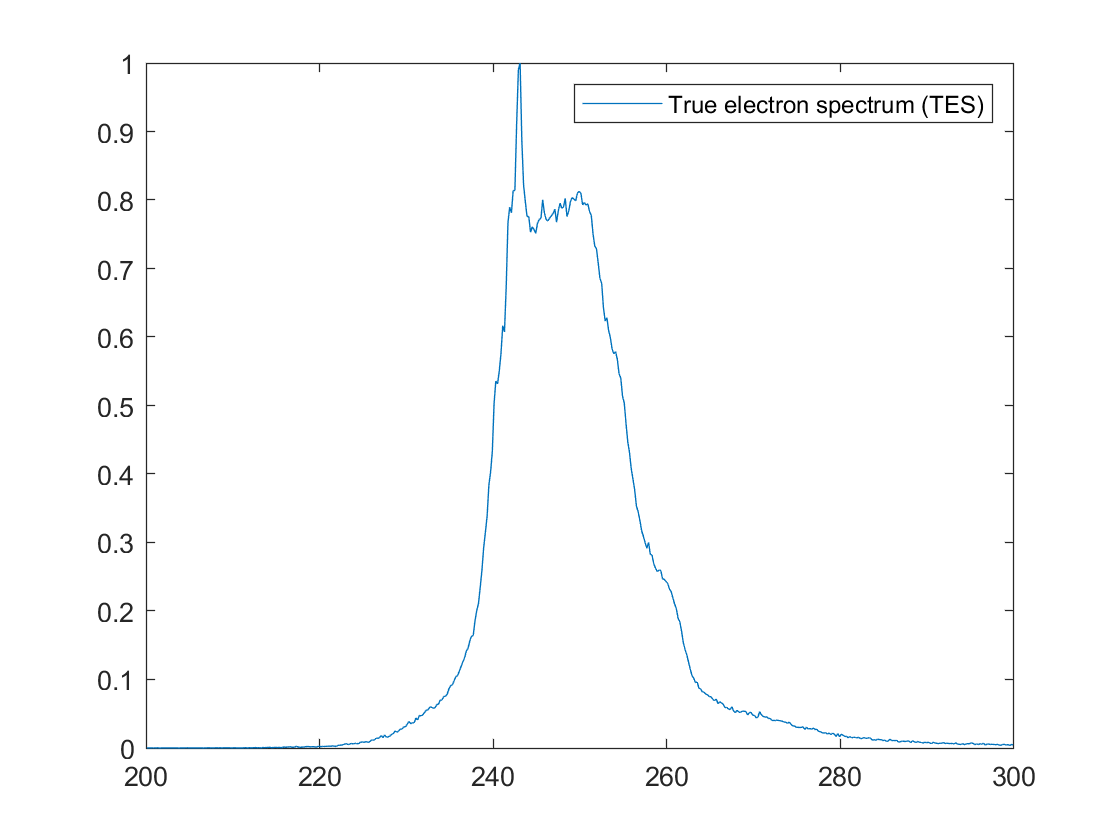



% calculates true electron spectra TES = ES - BES
TES_1= ES_1 - BES_1;

figure
plot(centres,TES_1/max(TES_1), 'DisplayName','True electron spectrum (TES)')
legend